# 前日までのレーティングから試合結果を予測し，対数損失と較正値を算出する．

## 2000年以降の全シーズンについてEloレーティングで予測する．

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');
seasonStartYearVals=unique(tbl_results.SeasonStartYear);

予測性能を保存する変数を用意する

PredictedMatches=[];    %予測対象の試合数
CorrectsByElo=[];      %Eloで予測した予測正解数
LogLossByElo=[];    %Eloで予測した場合の対数損失
CalibValByElo=[];   %Eloで予測した場合の較正値
AUCByElo=[];    %Eloで予測した場合のAUC

計算を早くするため，チーム名などを数値に変換しておく

matchData=zeros(size(tbl_results,1),4);
teamNames=unique(tbl_teams.TeamName);
for n1=1:size(tbl_results,1)
    TeamAName=tbl_results.Home(n1);
    TeamBName=tbl_results.Away(n1);
    TeamANum=find(teamNames== TeamAName);
    TeamBNum=find(teamNames== TeamBName);
    matchData(n1,1)=TeamANum;
    matchData(n1,2)=TeamBNum;
    matchData(n1,3)=tbl_results.HomeScore(n1);
    matchData(n1,4)=tbl_results.AwayScore(n1);
end

実際の勝敗

ActualWin=matchData(:,3)>matchData(:,4);

ホームチームの勝率

pWin_home=mean(ActualWin)

pWin_home = 0.5993

### Eloレーティングを計算する

- シーズンが変わった時に初期化する

- 予測対象試合でなくても計算しておく(予測対象試合は後で抽出しなおす)

r=zeros(size(teamNames));
EloRatings=zeros(size(matchData,1),2);

(ホームアドバンテージを設定できるようにしてあります)

K=16;
homeAdv=0;%400*log10(pWin_home/(1-pWin_home))
for n1=1:size(matchData,1)
    if n1>1 && ...
            (tbl_results.SeasonStartYear(n1)>tbl_results.SeasonStartYear(n1-1))
        r=zeros(size(teamNames));
    end

    TeamANum=matchData(n1,1);
    TeamBNum=matchData(n1,2);
    TeamARating=r(TeamANum);
    TeamBRating=r(TeamBNum);
    EloRatings(n1,1)=TeamARating+homeAdv;
    EloRatings(n1,2)=TeamBRating;
    wl=matchData(n1,3)>matchData(n1,4);
    wHat=1/(1+10^(-(TeamARating-TeamBRating)/400));
    r(TeamANum)=r(TeamANum)+K*(wl-wHat);
    r(TeamBNum)=r(TeamBNum)-K*(wl-wHat);

end

Eloレーティングによる予測

PredictionByElo=EloRatings(:,1)>EloRatings(:,2);
rateDiff=EloRatings(:,1)-EloRatings(:,2);
PredProbByElo=1./(1+10.^(-rateDiff/400));

シーズン開始年を指定しそれぞれについて集計する．

seasonStartYearVal = 2000

seasonStartYearVal = 2001

seasonStartYearVal = 2002

seasonStartYearVal = 2003

seasonStartYearVal = 2004

seasonStartYearVal = 2005

seasonStartYearVal = 2006

seasonStartYearVal = 2007

seasonStartYearVal = 2008

seasonStartYearVal = 2009

seasonStartYearVal = 2010

seasonStartYearVal = 2011

seasonStartYearVal = 2012

seasonStartYearVal = 2013

seasonStartYearVal = 2014

seasonStartYearVal = 2015

seasonStartYearVal = 2016

seasonStartYearVal = 2017

seasonStartYearVal = 2018

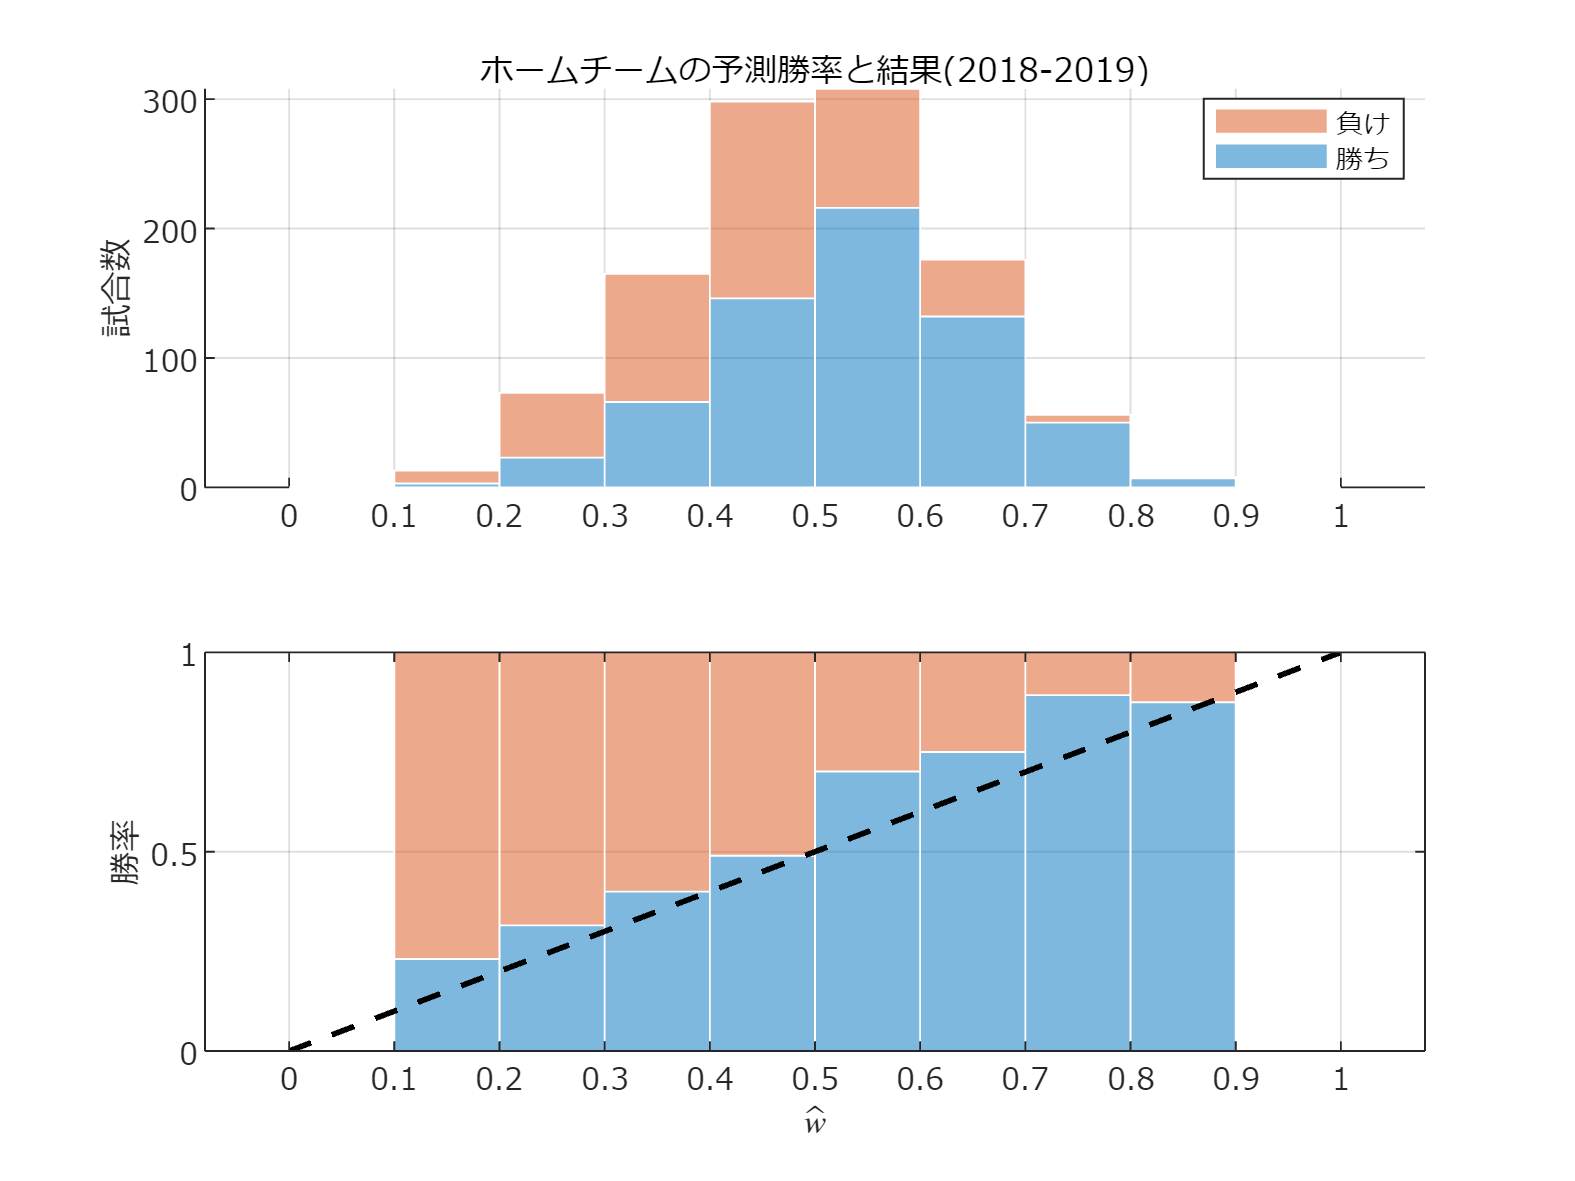

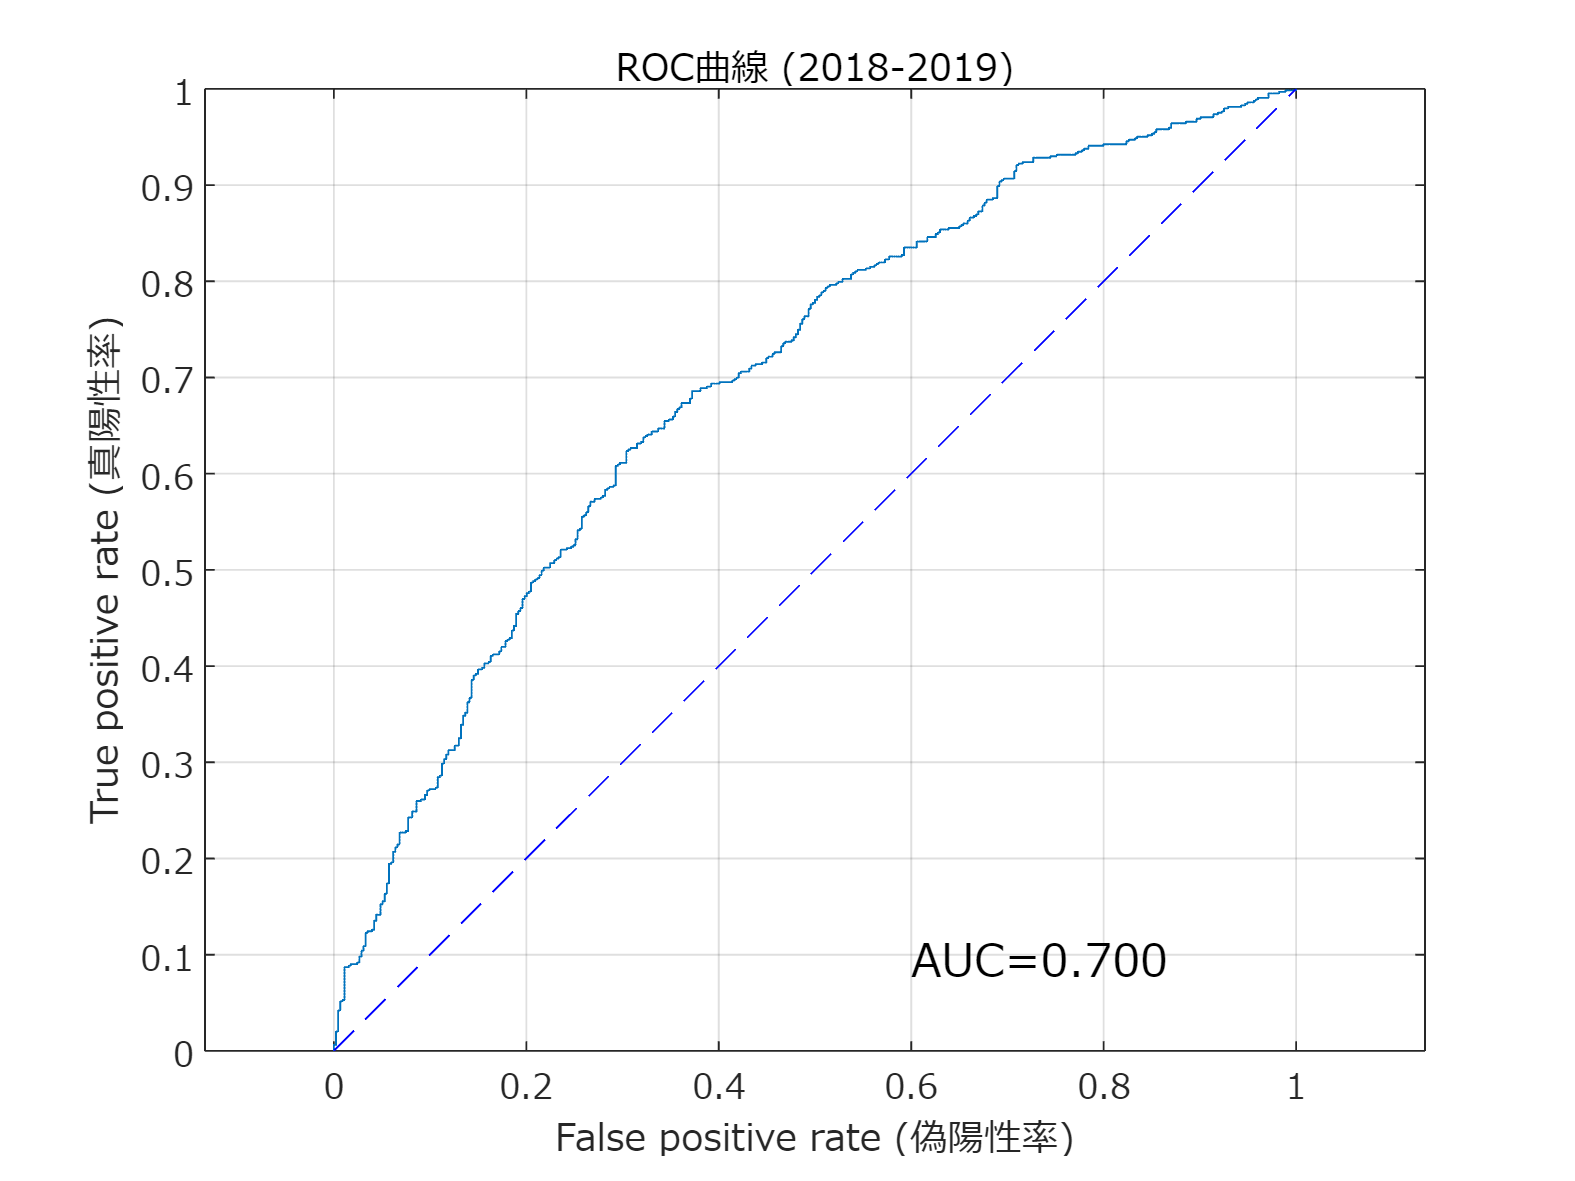

for seasonStartYearVal=seasonStartYearVals'
    seasonStartYearVal
    ind = tbl_results.SeasonStartYear==seasonStartYearVal;

予測対象の開始日を求める

    seasonStartDate=min(tbl_results.Date(ind));
    predictionStartDate=seasonStartDate+days(31);

テスト用(test)の試合結果の表を作る

    ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.Date>=predictionStartDate;

各指標の算出

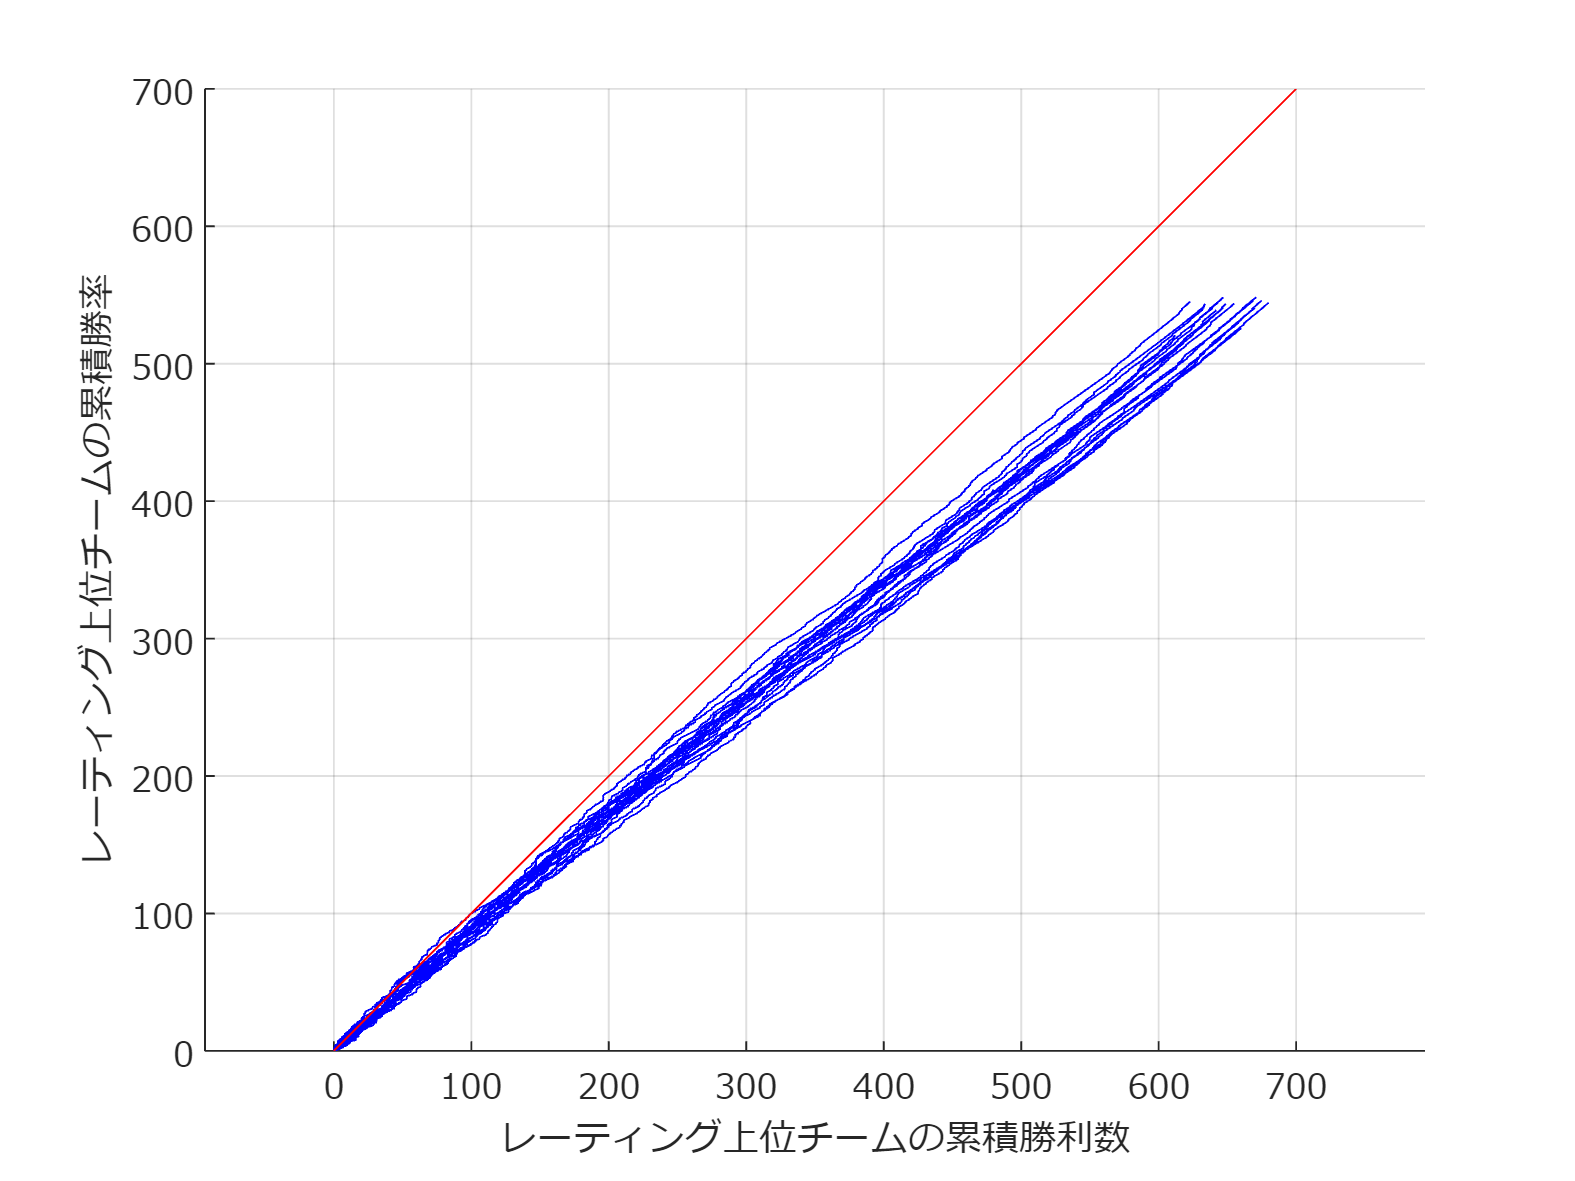

    PredictedMatches=[PredictedMatches;sum(ind)];

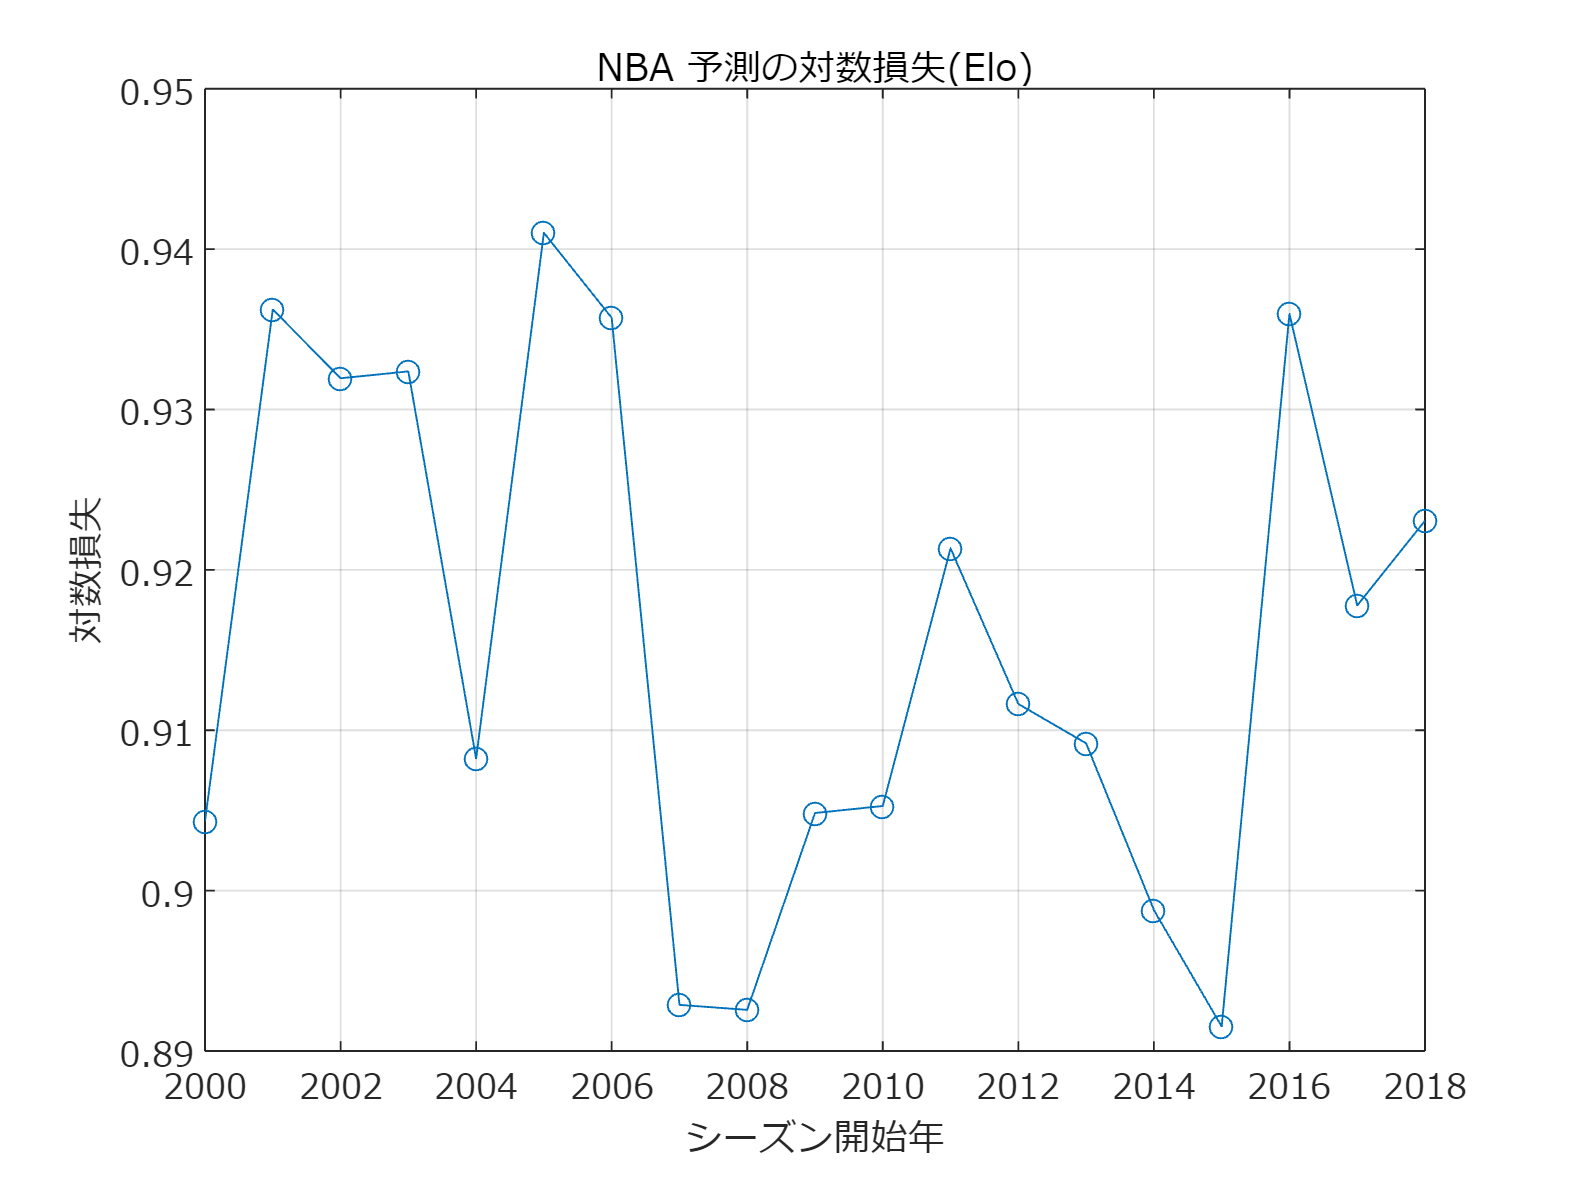

    CorrectsByElo=[CorrectsByElo;...
        sum(PredictionByElo(ind)==ActualWin(ind))];
    w=ActualWin(ind);   %対象試合の実際の勝敗
    wHat=PredProbByElo(ind);    %対象試合の予測勝率(ホームチームから見て)
    tmpLogLoss=-mean(w.*log2(wHat)+(1-w).*log2(1-wHat));    %対数損失
    LogLossByElo=[LogLossByElo;tmpLogLoss];

    ind2=wHat>0.5;  %ホームチームを優位と予測した試合

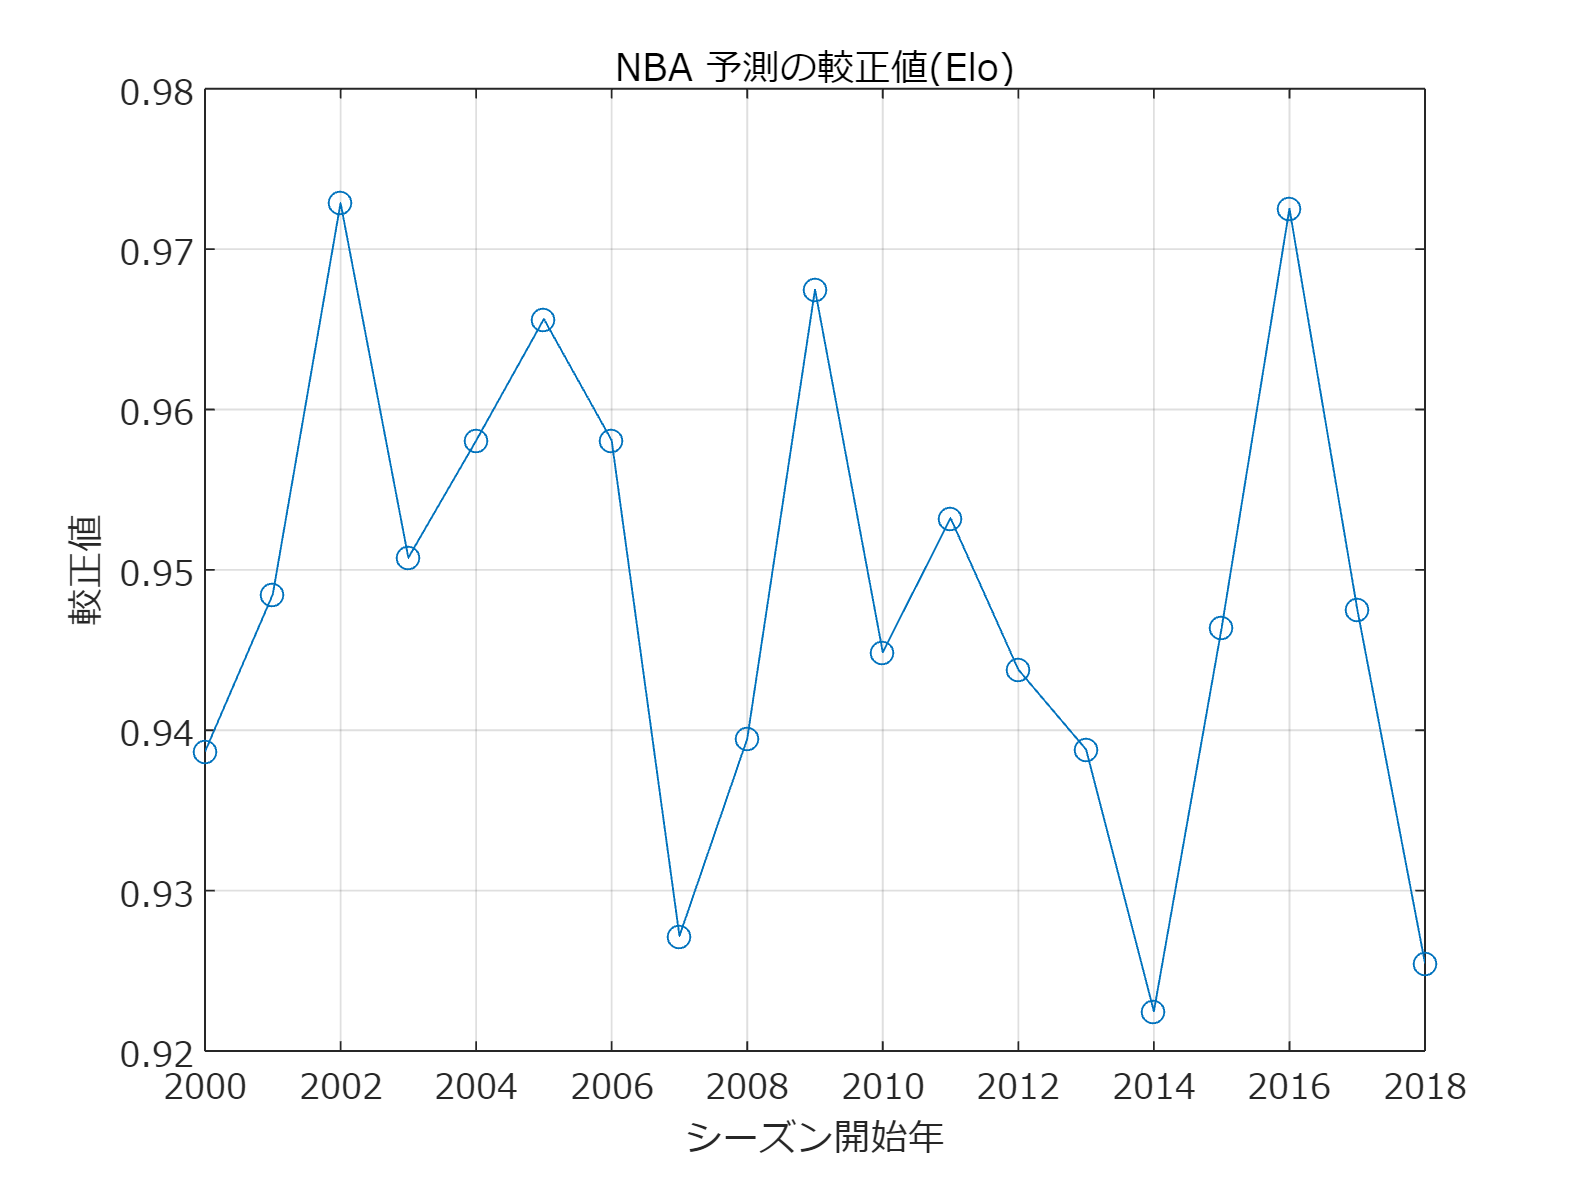

    tmpSumActualWin=sum(w(ind2))+sum(1-w(~ind2));  %優位チームの実際の勝利数
    tmpSumPredWin=sum(wHat(ind2))+sum(1-wHat(~ind2));   %優位チームの勝率の合計
    tmpCalibVal=tmpSumPredWin/tmpSumActualWin;
    CalibValByElo=[CalibValByElo;tmpCalibVal];

    [~, ~, ~, AUCVal] ...
        =perfcurve(ActualWin(ind),PredProbByElo(ind),1);
    AUCByElo=[AUCByElo;AUCVal];

予測勝率の小さい順にソートし，予測勝率と実勝利それぞれの累積を計算・図示する．

    figure(1);
    hold on;grid on;axis equal;
    set(gca,'fontname','メイリオ');
    [~,ind3]=sort(wHat);
    plot(cumsum(w(ind3)),cumsum(wHat(ind3)),'b-');
    hold off

ホームチームの予測勝率の分布(2018-2019シーズンのみ)

ROC曲線の描画(2018-2019シーズンのみ)

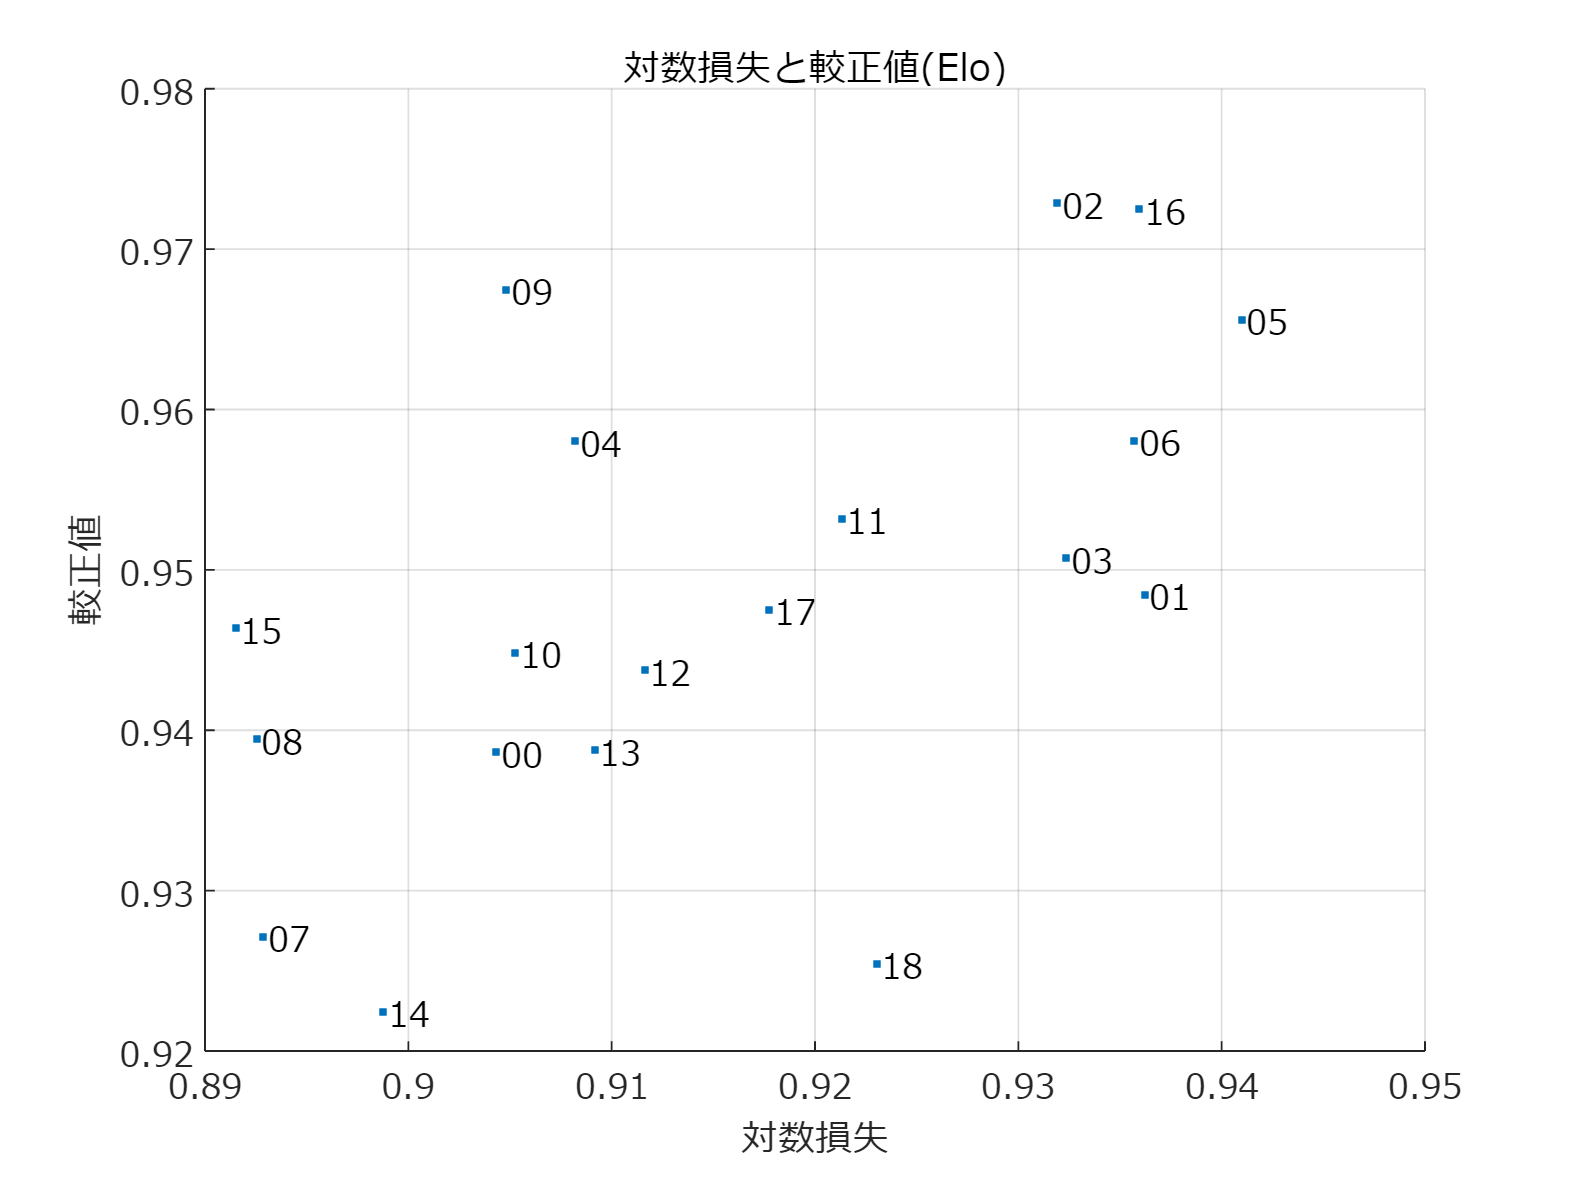

    if seasonStartYearVal==2018
        figure;
        tiledlayout(2,1);
        nexttile;
        edges=0:0.1:1;
        ind_win=ind & ActualWin==1;
        ind_lose=ind & ActualWin==0;


        histcWin=histcounts(PredProbByElo(ind_win),edges);hold on;grid on;
        histcLose=histcounts(PredProbByElo(ind_lose),edges);
        bar(movmean(edges,2,"Endpoints","discard"),...
            [histcWin;histcLose], ...
            'stacked', 'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
        set(gca,'fontname','メイリオ')
        legend({'勝ち','負け'},'FontName','メイリオ','Location','best');
        ylabel('試合数');
        title('ホームチームの予測勝率と結果(2018-2019)')
        nexttile;
        bar(movmean(edges,2,"Endpoints","discard"),...
            [histcWin;histcLose]./(histcWin+histcLose), ...
            'stacked', 'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
        grid on;hold on;
        set(gca,'fontname','メイリオ');
        xlabel('$\hat{w}$','Interpreter','latex');
        ylabel('勝率');
        plot([0 1],[0 1],'k--','LineWidth',1.5)
        exportgraphics(gcf,'fig_NBAPredictionByElo-Histogram.pdf');

        [tmpX, tmpY, tmpT, AUCVal] ...
            =perfcurve(ActualWin(ind),PredProbByElo(ind),1);

        figure
        plot(tmpX, tmpY);grid on;hold on;axis equal;
        plot([0 1],[0 1],'b--');
        text(0.6,0.1,['AUC=' num2str(AUCVal,'%1.3f')],'fontname','メイリオ','FontSize',12);
        set(gca,'fontname','メイリオ');
        xlabel('False positive rate (偽陽性率)');
        ylabel('True positive rate (真陽性率)');
        title('ROC曲線 (2018-2019)')
    end
end

以下の図では青線が赤線(実勝利数=予測勝率の合計を示す)に沿っているほど良い予測であることを示す．

figure(1);hold on;
plot([0 700],[0 700],'r-');
xlabel('レーティング上位チームの累積勝利数');
ylabel('レーティング上位チームの累積勝率')
hold off;
figure;
plot(seasonStartYearVals, LogLossByElo,'o-');
hold on;grid on;

set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('対数損失');
title('NBA 予測の対数損失(Elo)');
exportgraphics(gcf,'fig_NBAPredictionByElo-LogLoss.pdf');
figure;
plot(seasonStartYearVals, CalibValByElo,'o-');
hold on;grid on;

set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('較正値');
title('NBA 予測の較正値(Elo)');
exportgraphics(gcf,'fig_NBAPredictionByElo-CalibVal.pdf');
figure
scatter(LogLossByElo, CalibValByElo,'.');
hold on;grid on;
set(gca,'fontname','メイリオ');
text(LogLossByElo+0.0002, CalibValByElo, ...
    num2str(seasonStartYearVals-2000,'%02d'),'FontName','メイリオ');
xlabel('対数損失');ylabel('較正値');title('対数損失と較正値(Elo)');
if homeAdv==0
    exportgraphics(gcf,'fig_NBAPredictionByElo-LogLoss-CalibVal.pdf');
    save('../data/data_NBAPredictionByElo.mat',"LogLossByElo","CalibValByElo");
else
    exportgraphics(gcf,'fig_NBAPredictionByElo-LogLoss-CalibVal-homeAdv.pdf');
end